## Project

Introduction

## 1. Data Load

- dt: the time interval

- K: max iterations

- N: Number of Agents (7)

- M: Number of Edges (12)

- Z: Actual positions of each agent (2D position)

- Z*: Target positions of each agent

- L: Edge weights ($l_{ij} $: the weight of the edge between positions of the i-th and j-th agent)

load("data.mat");

## 2. Initialization

L;
z_matrix = zeros(7, 2, K); % matrix of positions of all agents
z_matrix(:, :, 1) = z;     % initialize the 1-st position
k = 1; % current iteration
% u_matrix = zeros(7, 2, K) % input matrix

## 3. Control without Noise

这里根据已给代码进行计算

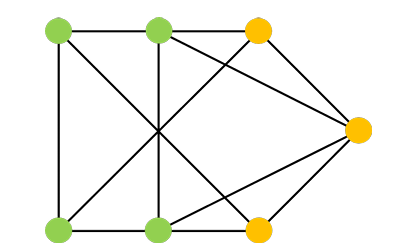

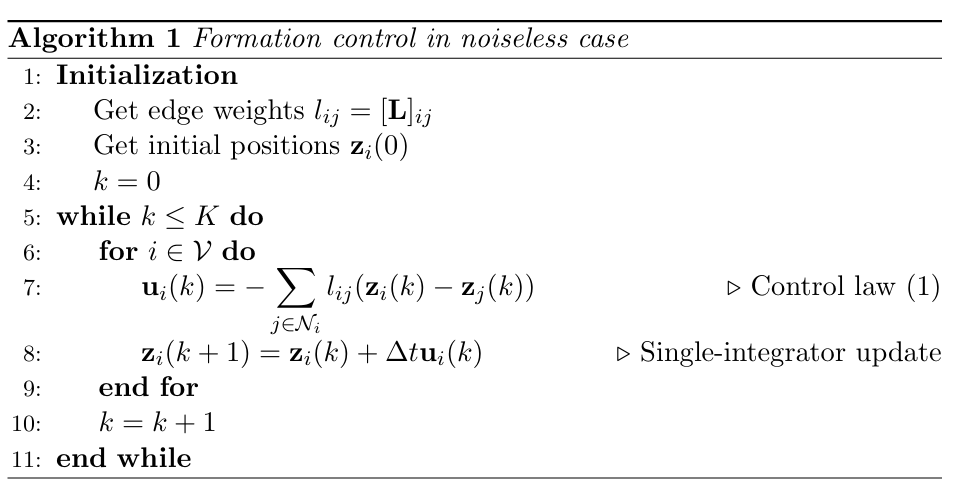

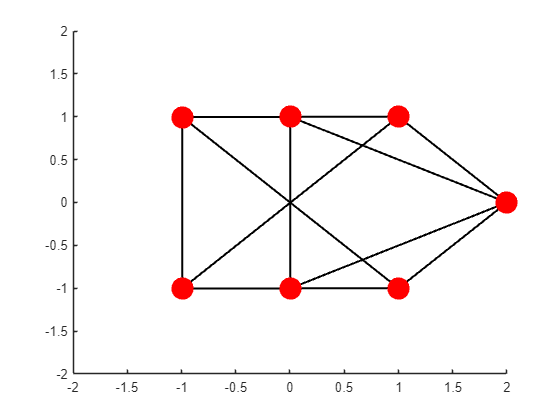

dt = 0.05;
K = 5000;
while k<=K
    for i = 1:N
 
        % 对k时刻的第ui进行计算 (ui(k))
        u_i_k = zeros(1, 2);
        z_i_k = z_matrix(i, :, k);

        for j = 1:N % 遍历L(i, j), 计算ui(k)
            u_i_k = u_i_k + L(i, j) * (z_matrix(i, :, k) - z_matrix(j, :, k));
        end
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end
        % 计算zi(k+1) = zi(k) + dt*ui(k)
        z_i_k_new = z_i_k + dt * u_i_k;
        z_matrix(i, :, k+1) = z_i_k_new;   % 赋值给z_matrix
    end
    k = k + 1;
    
end
error = compute_error(z_matrix, z_star, K);        % 计算误差
plot_formation(z_matrix(:, :, K));

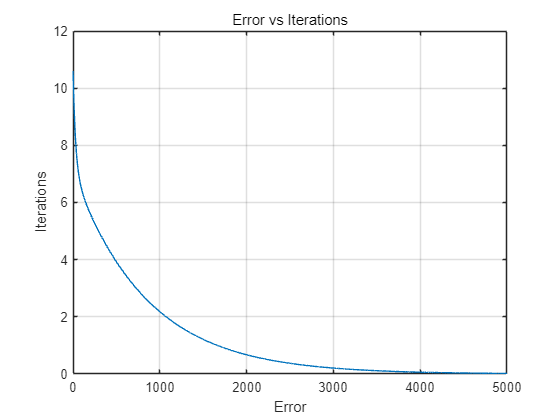

figure(2);
plot(error); 
xlabel("Error");
ylabel("Iterations");
title("Error vs Iterations");
grid on;

### 4. Add Noise and Observation

该部分为展示噪声给结果带来的不稳定影响

根据R施加噪声，总的来说会有收敛趋势，但是最后没办法收敛到理想位置

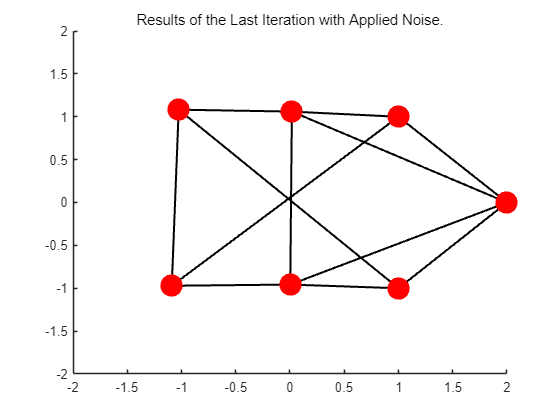

z_matrix2 = zeros(7, 2, K);
z_matrix2(:, :, 1) = z;
k = 1;
observations_m = zeros(12, 2, K);           % 用于保留观测值，因为一共只有12条边非0，所以只需要12个向量
while k<=K
    state_num = 0;
    for i = 1:N


        % 对k时刻的第ui进行计算 (ui(k))
        u_i_k = zeros(1, 2);
        z_i_k = z_matrix2(i, :, k);
        
        for j = 1:N % 遍历L(i, j), 计算ui(k)
            x_state = z_matrix2(i, :, k) - z_matrix2(j, :, k) + mvnrnd([0, 0], R);
            u_i_k = u_i_k + L(i, j) * x_state;
            %

            % x_matrix(i, j, :, k) = x; % 这样操作有问题，因为实际观测只需要看L不为0的
            % 状态量保留
            % 1. 只保留L不为0且非自环的观测值
            % 2. 只保留下三角矩阵中L不为0的值（因为L是对称矩阵）
            if(L(i, j)~=0 && i<j)
                state_num = state_num + 1;
                observations_m(state_num, :, k) = x_state;
            end
        end
        
        % 如果计算的是第i个智能体的输入，那么设为0，因为他们不会变化位置
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end

        % 计算zi(k+1) = zi(k) + dt*ui(k)
        z_i_k_new = z_i_k + dt * u_i_k;
        z_matrix2(i, :, k+1) = z_i_k_new;   % 赋值给z_matrix
    end
    k = k + 1;
    
end

error = compute_error(z_matrix2, z_star, K);        % 计算误差
x = 1:5000;     % 坐标轴
plot_formation(z_matrix2(:, :, K));
title("Results of the Last Iteration with Applied Noise.")

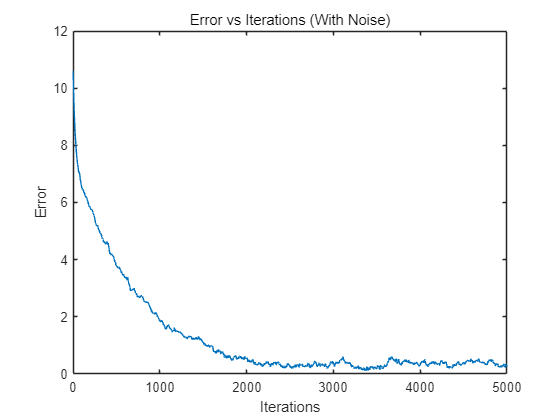

figure;
plot(x, error);
xlabel("Iterations");
ylabel("Error");
title("Error vs Iterations (With Noise)");

## 5. Applying Different Estimators

% 这里设置估计器的共同参数，用于对比
max_iter = 2000;    % 最大迭代次数
T = 20;             % 每对节点的观测次数
dt = 0.1;          % 步长

## 5.1 实现无偏估计器


z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵 (7个节点，2维，k次迭代)
z_matrix_2(:, :, 1) = z; % 初始状态
state_matrix = zeros(24, 2, max_iter); % 保存每次迭代的平均状态
noise_matrix = zeros(24, 2, max_iter); % 保存每次迭代的平均噪声
k = 1; % 当前迭代次数

vec_T = ones(T, 1);
dimension = 2;
I_Dimension = eye(2);


for k = 1:max_iter
    for i = 1:N
        % 初始化输入
        u_i_k = zeros(1, dimension);
        
        % 遍历邻居节点
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % 构造测量值
                vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T)));
                H = kron(vec_T, I_Dimension);
                dz = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);
                x_state_m = H * dz' + vij_m';
                
                % 计算平均观测值
                x_avg = (1 / T) * kron(vec_T', I_Dimension) * x_state_m;
                
                % 累加输入
                u_i_k = u_i_k + L(i, j) * x_avg';
            end
        end
        
        % 更新状态（固定节点不更新）
        if i == 1 || i == 2 || i == 3
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new;
    end
end



## 可视化最终结果（无偏估计器）

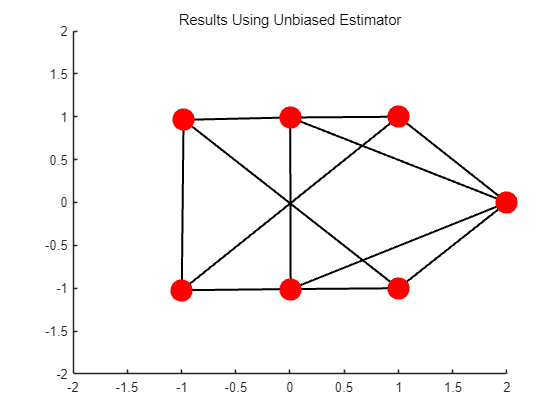

figure;
plot_formation(z_matrix_2(:, :, max_iter));
title("Results Using Unbiased Estimator");

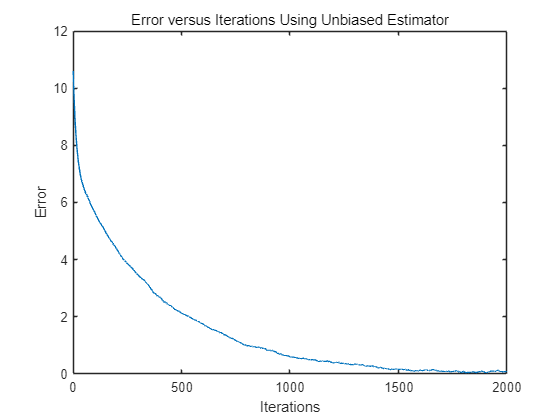

error_Unbiased = compute_error(z_matrix_2, z_star, max_iter);
figure;
plot(error_Unbiased);

xlabel("Iterations");
ylabel("Error");
title("Error versus Iterations Using Unbiased Estimator");

## 5.2 MLE估计器

% 初始化参数

z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵
z_matrix_2(:, :, 1) = z;                % 初始状态
T = 10;                                 % 每对节点的观测次数
vec_T = ones(T, 1);                     % T x 1 全1向量
dimension = 2;                          % 状态维度
I_Dimension = eye(dimension);           % D x D 单位矩阵

% 开始迭代
for k = 1:max_iter
    for i = 1:N
        % 初始化输入
        u_i_k = zeros(1, dimension);
        
        % 遍历邻居节点
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % 构造测量值
                vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T)));
                H = kron(vec_T, I_Dimension);
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);
                x_state_m = H * dz_true' + vij_m'; % 带噪声的观测值
                
                % 计算 MLE 解
                Sigma_v = kron(R, eye(T)); % 协方差矩阵
                Sigma_v_inv = inv(Sigma_v); % 逆矩阵
                dz_mle = inv(H' * Sigma_v_inv * H) * H' * Sigma_v_inv * x_state_m; % MLE 解
                
                % 累加输入
                u_i_k = u_i_k + L(i, j) * dz_mle';
            end
        end
        
        % 更新状态（固定节点不更新）
        if i == 1 || i == 2 || i == 3
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new;
    end
end


## 可视化最终结果（MLE）

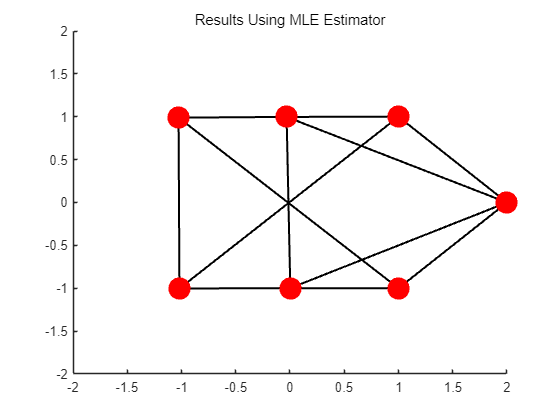


figure;
plot_formation(z_matrix_2(:, :, max_iter)); % 绘制最终状态
title("Results Using MLE Estimator");

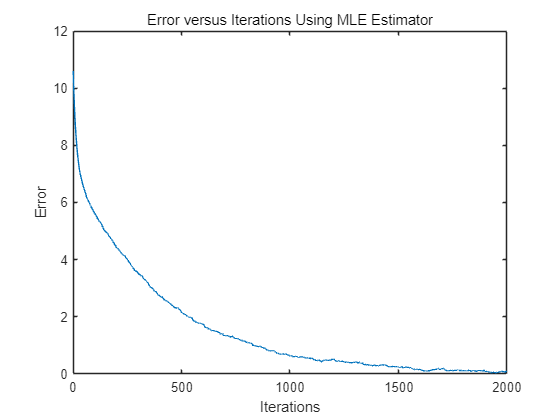

figure;
error_MLE = compute_error(z_matrix_2, z_star, max_iter);
title("Results Using MLE Estimator");
plot(error_MLE);
xlabel("Iterations");
ylabel("Error");
title("Error versus Iterations Using MLE Estimator");

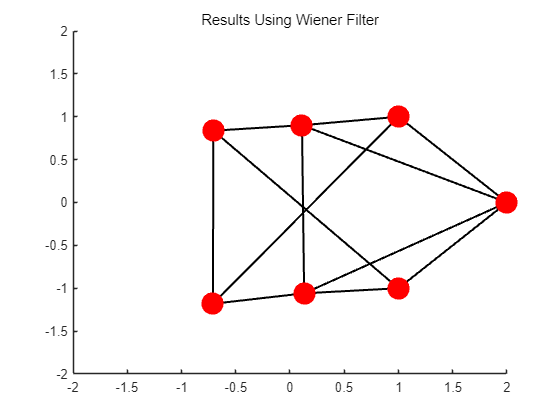


%% 5.3 Wiener估计器
% 初始化参数
z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵 (7个节点，2维，k次迭代)
z_matrix_2(:, :, 1) = z;                % 初始状态
dimension = 2;                          % 状态维度
vec_T = ones(T, 1);                     % T x 1 全1向量
I_Dimension = eye(dimension);           % D x D 单位矩阵
R = [0.1, 0; 0, 0.2];                   % 测量噪声协方差
Q = 0.01 * eye(dimension);              % 状态噪声协方差

% 构造测量矩阵
H = kron(vec_T, I_Dimension);           % TD x D 测量矩阵
Sigma_v = kron(R, eye(T));              % TD x TD 测量噪声协方差矩阵

% 计算维纳滤波器权重矩阵 W
W = Q * H' / (H * Q * H' + Sigma_v);    % D x TD 滤波器权重矩阵

% 迭代过程
for k = 1:max_iter
    for i = 1:N
        % 初始化输入
        u_i_k = zeros(1, dimension);
        
        % 遍历邻居节点
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % 生成带噪声的观测值
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k); % 相对状态
                vij_m = mvnrnd(zeros(1, T * dimension), Sigma_v); % 噪声
                x_state_m = H * dz_true' + vij_m'; % 带噪声测量值
                
                % 使用维纳滤波器估计 dz
                dz_estimate = W * x_state_m; % 维纳滤波器的估计结果
                
                % 累加输入
                u_i_k = u_i_k + L(i, j) * dz_estimate';
            end
        end
        
        % 更新状态（固定节点不更新）
        if i == 1 || i == 2 || i == 3
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new; % 保存更新后的状态
    end
end

% 可视化最终结果
figure;
plot_formation(z_matrix_2(:, :, max_iter)); % 自定义绘图函数
title("Results Using Wiener Filter");

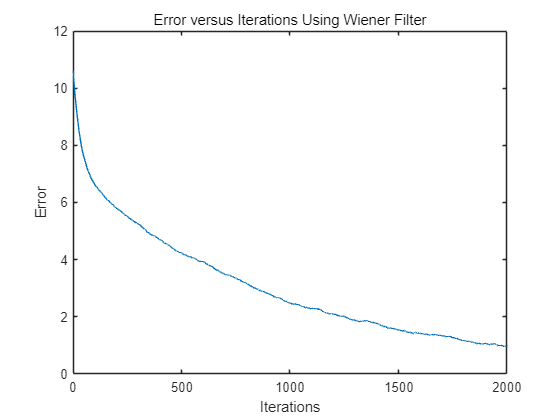

error_Wiener = compute_error(z_matrix_2, z_star, max_iter);
figure;
plot(error_Wiener);
xlabel("Iterations");
ylabel("Error");
title("Error versus Iterations Using Wiener Filter");